load('final.mat')
%% Estimador de Peso com Base em Regressão Linear
% Este script estima o peso de uma nova empenagem (horizontal e vertical)
% usando apenas regressão linear.

%% Dados das Empenagens Anteriores
areas_h = [0.122, 0.089, 0.158, 0.195]; % Áreas das empenagens horizontais (m²)
pesos_h = [96.8, 88.49, 126, 134];    % Pesos das empenagens horizontais (g)

areas_v = [0.039, 0.08, 0.108];  % Áreas das empenagens verticais (m²)
pesos_v = [60, 64.85, 72.4,];     % Pesos das empenagens verticais (g)

%% Verificação dos Dados
disp('Dados das empenagens horizontais:');

Dados das empenagens horizontais:


disp(table(areas_h', pesos_h', 'VariableNames', {'Área (m²)', 'Peso (g)'}));

    Área (m²)    Peso (g)
    _________    ________

      0.122        96.8  
      0.089       88.49  
      0.158         126  
      0.195         134  




disp('Dados das empenagens verticais:');

Dados das empenagens verticais:


disp(table(areas_v', pesos_v', 'VariableNames', {'Área (m²)', 'Peso (g)'}));

    Área (m²)    Peso (g)
    _________    ________

      0.039          60  
       0.08       64.85  
      0.108        72.4  



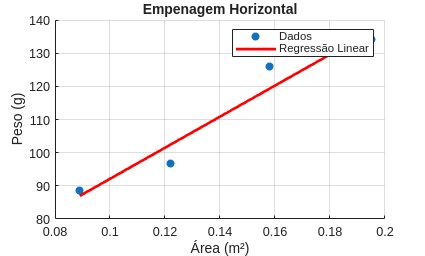


%% Ajuste de Modelos de Regressão
% Modelo linear para as empenagens
coef_h = polyfit(areas_h, pesos_h, 1); % Regressão linear (1º grau)
coef_v = polyfit(areas_v, pesos_v, 1); % Regressão linear (1º grau)

%Empenagem horizontal
figure; % Cria uma nova figura
scatter(areas_h, pesos_h, 'filled'); % Plota os pontos
hold on;
x_h = linspace(min(areas_h), max(areas_h), 100); % Define os valores de x para a linha
y_h = polyval(coef_h, x_h); % Calcula os valores de y usando o modelo ajustado
plot(x_h, y_h, 'r-', 'LineWidth', 2); % Plota a linha de regressão
title('Empenagem Horizontal');
xlabel('Área (m²)');
ylabel('Peso (g)');
grid on;
legend('Dados', 'Regressão Linear');

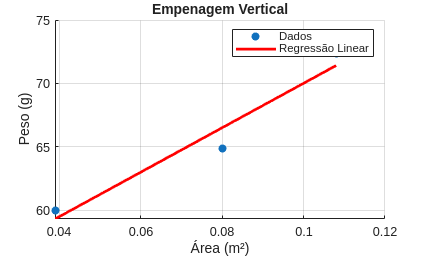


% Empenagem vertical
figure; % Cria uma nova figura
scatter(areas_v, pesos_v, 'filled'); % Plota os pontos
hold on;
x_v = linspace(min(areas_v), max(areas_v), 100); % Define os valores de x para a linha
y_v = polyval(coef_v, x_v); % Calcula os valores de y usando o modelo ajustado
plot(x_v, y_v, 'r-', 'LineWidth', 2); % Plota a linha de regressão
title('Empenagem Vertical');
xlabel('Área (m²)');
ylabel('Peso (g)');
grid on;
legend('Dados', 'Regressão Linear');

## Parâmetros da Nova Empenagem para Estimativa



fprintf('Sh da nova: %.5f g\n', Sh);

Sh da nova: 0.20000 g


fprintf('Sv da nova: %.5f g\n', Sv);

Sv da nova: 0.03600 g



%% Estimativa do Peso
% Cálculo do peso estimado com base nos modelos ajustados
peso_horizontal = polyval(coef_h, Sh);
peso_vertical = polyval(coef_v, Sv);

%% Análise de Resíduos
% Resíduos para empenagem vertical
pesos_v_previstos = polyval(coef_v, areas_v);
residuos_v = pesos_v - pesos_v_previstos;

%% Resultados
% Exibição do peso estimado
fprintf('Peso estimado da empenagem horizontal: %.2f g\n', peso_horizontal);

Peso estimado da empenagem horizontal: 138.96 g


fprintf('Peso estimado da empenagem vertical: %.2f g\n', peso_vertical);

Peso estimado da empenagem vertical: 58.80 g


fprintf('Peso total estimado (horizontal + vertical): %.2f g\n', peso_horizontal + peso_vertical);

Peso total estimado (horizontal + vertical): 197.76 g



% Exibição da análise de resíduos
disp('Resíduos (vertical):');

Resíduos (vertical):


disp(table(areas_v', pesos_v', pesos_v_previstos', residuos_v', ...
    'VariableNames', {'Área (m²)', 'Peso Real (g)', 'Peso Previsto (g)', 'Resíduo (g)'}));

    Área (m²)    Peso Real (g)    Peso Previsto (g)    Resíduo (g)
    _________    _____________    _________________    ___________

      0.039             60             59.327            0.67326  
       0.08          64.85             66.509            -1.6591  
      0.108           72.4             71.414            0.98585  



save('limitacao_motor.mat')

## LIMITACAO 2025

[p,d2,peso_motor,d1,x,dtotal,Ajmotor]=lim_2025(lh,peso_horizontal,lv, peso_vertical, Sh,bh,bw);

d1 = 0.171571


fprintf('ajsute: %.3f m\n', Ajmotor);

ajsute: 0.091 m


fprintf('total: %.3f m\n', dtotal);

total: 3.409 m


function [p1,d2,p2,d1,x,dtotal,Ajmotor]=lim_2025(lh,peso_horizontal,lv, peso_vertical, Sh,bh,bw);
  p1=416.1; %Peso do motor (g)
   d2= 0.12; %Distancia do CG da aeronave ate os componentes eletrico (m)
   p2=961; %Peso dos componentes eletricos
   p3 = 32; %Peso dos serves do EH e EV (g)
   d1=((-p2*d2)+(lh*(peso_horizontal+p3))+(lv*(p3+peso_vertical)))/p1; %Distancia do CG da Aeronave ate o CG do motor
      fprintf('d1 = %f\n', d1);

      
   x= 0.75*(Sh/bh)+lh+ d1; %distantcia do motor ate o profundor
   dtotal= x + bw; % Calculo do Edital 
   Ajmotor= 3.5 - dtotal;
end
save('finalizado.mat')
